# Lab 9: If-Else statement

## 1.    Whether a storm is a tropical depression, tropical storm, or hurricaneis determined by the average sustained wind speed. In miles per hour, a storm is a tropical depression if the winds are less than 38 mph.  It is a tropicalstorm if the winds are between 39 and 73 mph, and it is a hurricaneif the wind speeds are >= 74 mph. Write a script that will prompt the user for the wind speed of the storm, and will print which type of storm it is.

% Prints whether a storm is a tropical depression, 
% tropical storm, or hurricane based on wind speed

wind = input('Enter the wind speed of the storm: '); 
if wind < 38
    disp('Tropical depression') 
elseif wind >= 38 && wind < 73
    disp('Tropical storm')
else
    disp('Hurricane')
end

Tropical storm


## 2.    In aerodynamics, the Mach number is a critical quantity. It is defined as the ratio of the speed of an object (e.g., an aircraft) to the speed of sound.  If theMach number is less than 1, the flow is subsonic; if the Mach number is equal to 1, the flow is transonic; if the Mach number is greater than 1, the flow is supersonic. Write a script that will prompt the user for the speed of an aircraft and the speed of sound at the aircraft’s current altitude and will print whether the condition is subsonic, transonic, or supersonic.

% Prints whether the speed of an object is subsonic, 
% transonic, or supersonic based on the Mach number

plane_speed = input('Enter the speed of the aircraft: '); 
sound_speed = input('Enter the speed of sound: ');
mach = plane_speed/sound_speed;

if mach < 1
disp('Subsonic') 
elseif mach == 1
disp('Transonic')
else
    disp('Supersonic')
end

Supersonic


## 3.    In a script, the user is supposed to enter either a ‘y’ or ‘n’ in responseto a prompt. The user’s input is read into acharacter variable called “letter”. The script will print “OK, continuing” if the user enters either a ‘y’ or ‘Y’ or it will print “OK, halting” if the user enters a ‘n’ or ‘N’ or “Error” if the user enters anythingelse. Put this statement in the scriptfirst:

## `letter` `=` `input('Enter` `your` `answer:` `',` `'s');`

## Write the scriptusing a singlenested **if-else** statement (**elseif** clause is permitted).

% Prompts the user for a 'y' or 'n' answer and responds
% accordingly, using an if-else statement
letter = input('Enter your answer: ', 's'); 
if letter == 'y' || letter == 'Y'
disp('OK, continuing')
elseif letter == 'n' || letter == 'N' 
    disp('OK, halting')
else
    disp('Error')
end

OK, continuing


## 4.    Write a function *flipvec *that will receive one input argument. If the input argument is a row vector, the function will reverse the order and returna new row vector. If the input argument is a columnvector, the function will reversethe order and return a new column vector. If the input argument is a matrixor a scalar, the function will return the input argument unchanged.

% function out = flipvec(vec)
% % Flips it if it's a vector, otherwise
% % returns the input argument unchanged
% % Format of call: flipvec(vec)
% % Returns flipped vector or unchanged 
% [r, c] = size(vec);
% if r == 1 && c > 1
%     out = fliplr(vec); 
% elseif c == 1 && r > 1 
%     out = flipud(vec);
% else
%     out = vec;
% end
% end

% flipvec([1 2 3 4 5])
% 
% ans =
% 
%      5     4     3     2     1
% 
% flipvec([1; 2; 3; 4; 5])
% 
% ans =
% 
%      5
%      4
%      3
%      2
%      1

## 5.    Write a function *eqfn* thatwill calculate $f\left(x\right)=x^2 +\frac{1}{x}$ for all elementsof x. Since divisionby 0 is not possible, if any element in x is zero, the function will instead return a flag of -99.

% function fofx = eqfn(x) 
% if any(any(x==0))
%     fofx = -99;
% else
%     fofx = x.^2 + 1./x;
% end
% end

% eqfn(5)
% 
% ans =
% 
%    25.2000

# for-end loop

## 6.    In the Command Window, write a **for** loop that will iterate through the integers from 32 to 255. For each, show the corresponding character from the character encoding. Play with this! Try printing characters beyond the standard ASCII, in small groups. For example, print the characters that correspond to integers from 300 to 340.

for i = 32:255 
    disp(char(i))
end

 
!
"
#
$
%
&
'
(
)
*
+
,
-
.
/
0
1
2
3
4
5
6
7
8
9
:
;
<
=
>
?
@
A
B
C
D
E
F
G
H
I
J
K
L
M
N
O
P
Q
R
S
T
U
V
W
X
Y
Z
[
\
]
^
_
`
a
b
c
d
e
f
g
h
i
j
k
l
m
n
o
p
q
r
s
t
u
v
w
x
y
z
{
|
}
~

































 
¡
¢
£
¤
¥
¦
§
¨
©
ª
«
¬
­
®
¯
°
±
²
³
´
µ
¶
·
¸
¹
º
»
¼
½
¾
¿
À
Á
Â
Ã
Ä
Å
Æ
Ç
È
É
Ê
Ë
Ì
Í
Î
Ï
Ð
Ñ
Ò
Ó
Ô
Õ
Ö
×
Ø
Ù
Ú
Û
Ü
Ý
Þ
ß
à
á
â
ã
ä
å
æ
ç
è
é
ê
ë
ì
í
î
ï
ð
ñ
ò
ó
ô
õ
ö
÷
ø
ù
ú
û
ü
ý
þ
ÿ


## 7.    Write a function *sumsteps2* that calculates and returns the sum of 1 to *n* in steps of 2, where *n* isan argument passedto the function. For example,if 11 is passed, it will return1 + 3 + 5 + 7 + 9 + 11. Do this using a **for** loop. Calling the functionwill look like this:

## `>>` `sumsteps2(11)`

## `ans =` `36`

% function outsum = sumsteps2(n)
% % sum from 1 to n in steps of 2
% % Format of call: sumsteps2(n)
% % Returns 1 + 3 + ... + n
% 
% outsum = 0; 
% for i = 1:2:n
%     outsum = outsum + i;
% end
% end

% sumsteps2(18)
% 
% ans =
% 
%     81

## 8.    Write a script that will load data from a file into a matrix. Createthe data file first, and make sure that there is the same number of values on every line in the file so that it can be loaded into a matrix. Using a **for** loop, it will then create a subplot for every row in the matrix, and will plot the numbers from each row element in the Figure Window.

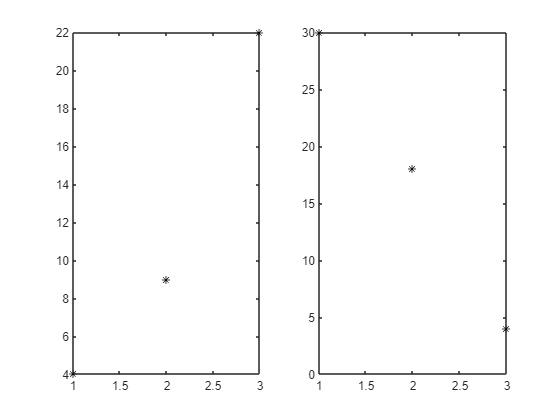

row1 = [4 9 22];
row2 = [30 18 4];
mat = [row1;row2];
% Save the matrix as an ASCII file.
save xfile.dat mat -ascii
% load data from a file and plot data
% from each line in a separate plot in a subplot
load xfile.dat
[r, c] = size(xfile); 
for i = 1:r
    subplot(1,r,i) 
    plot(xfile(i,:),'k*')
end

## 9.    Write a script that will print the followingmultiplication table:

## `1`

## `2` `4`

## `3` `6` `9`

## `4` `8` `12` `16`

## `5` `10` `15` `20` `25`

% Prints a multiplication table 
rows = 5;
for i = 1:rows 
%     for j = 1:i
%         fprintf('%d ', i*j)
%     end
%     fprintf('\n')
    linspace(i,i*i,i)
end

ans = 1

ans =      2     4


ans =      3     6     9


ans =      4     8    12    16


ans =      5    10    15    20    25


## 10.    A machine cuts N pieces of a pipe. After each cut, each piece of pipe is weighed and its length is measured; these 2 values are then stored in a file called *pipe.dat *(first the weight and then the length on each line of the file). Ignoring units, the weight is supposed to be between 2.1 and 2.3, inclusive, and the length is supposedto be between 10.3 and 10.4, inclusive.  The following is just the beginningof what will be a long script to work with these data.  For now, thescript will just count how many rejects there are. A reject is any piece of pipe that has an invalid weight and/or length. For a simple example, if N is 3 (meaningthree lines in the file) and the file stores:

## 2.14    10.30

## 2.32    10.36

## 2.20    10.35

## there is only one reject, the second one, as it weighs too much. The script would print: There were 1 rejects.

% Counts pipe rejects. Ignoring units, each pipe should be
% between 2.1 and 2.3 in weight and between 10.3 and 10.4
% in length
row1 = [2.44 10.40];
row2 = [2.23 10.36];
row3 = [2.20 12.35];
mat = [row1;row2;row3];
% Save the matrix as an ASCII file.
save pipe.dat mat -ascii
% read the pipe data and separate into vectors 
load pipe.dat
weights = pipe(:,1); 
lengths = pipe(:,2); 
N = length(weights);
% the programming method of counting 
count = 0;
for i=1:N
    if weights(i) < 2.1 || weights(i) > 2.3 || lengths(i) < 10.3 || lengths(i) > 10.4
        count = count + 1;
    end
end
fprintf('There were %d rejects.\n', count)

There were 2 rejects.
